# Entregable 2 - RETO

**Alexia Giselle Paz Jasso | A01635557**

**Diego Curiel Castellanos | A01640372**

**Santiago Vera Espinoza  | A01641585**

clc;
clear;
clf;

hold on;
axis equal;

%   Dimensiones placa positiva
a1 = 2;
l1 = 10;
h1 = 6;

%   Dimensiones placa negativa
a2 = 2;
l2 = 2;
h2 = 2;

%   Distancia entre placas
d = 9;

%   Activadores
qvr = 1;    % Activa el quiver para todo el código
qvr3d = 1;  % Activa el quiver en 3D

dl = abs(l1- l2)/2;
dh = abs(h1 - h2)/2;

% Posiciones Placas

dx1 = 0;
dy1 = 0;
dz1 = 0;

dx2 = a1 + d;
dy2 = 0 + dl;
dz2 = 0;

if h1>h2
    dz2 = dz2 + dh;
    pmh = h1/2;
else
    dz1 = dz1 + dh;
    pmh = h2/2;
end

% Ejes

distp = 10;

xmin = -distp;
xmax = dx2 + a2 + distp;
ymin = -distp;
ymax = dy2 + l2 + distp;
zmin = -distp;
zmax = dz2 + h2 + distp + dh;

verticesR1 = [0,l1,0;  % V1
              a1,l1,0;  % V2
              a1,0,0;  % V3
              0,0,0;  % V4
              0,l1,h1;  % V5
              a1,l1,h1;  % V6
              a1,0,h1;  % V7
              0,0,h1]; % V8

verticesR2 = [0,l2,0;  % V1
              a2,l2,0;  % V2
              a2,0,0;  % V3
              0,0,0;  % V4
              0,l2,h2;  % V5
              a2,l2,h2;  % V6
              a2,0,h2;  % V7
              0,0,h2]; % V8

verticesR1 = offset3D(verticesR1, dx1, dy1, dz1);
verticesR2 = offset3D(verticesR2, dx2, dy2, dz2);

carasR = [1 2 6 5;   % Cara 1
          2 3 7 6;   % Cara 2
          3 4 8 7;   % Cara 3
          4 8 5 1;   % Cara 4
          5 6 7 8;   % Cara 5
          1 2 3 4];  % Cara 6

patch('Faces', carasR, 'Vertices', verticesR1, 'Facecolor', 'r');
patch('Faces', carasR, 'Vertices', verticesR2, 'Facecolor', 'b');
view(30,30);
axis([xmin, xmax, ymin, ymax, zmin, zmax]);

k = 8.99e9;
Cd = 1;

if qvr3d == 1
    [xGrid, yGrid, zGrid] = meshgrid(xmin:4:xmax, ymin:4:ymax, zmin:4:zmax);
elseif qvr3d == 0
    [xGrid, yGrid] = meshgrid(xmin:4:xmax, ymin:4:ymax);
    zGrid = xGrid*0 + pmh;
end

%----------------Carga Neg 1-------------------- azul

Qn1 = -20;

dxn1 = dx2;
dyn1 = dy2;
dzn1 = 0 + h2/2;

Rxn1 = xGrid - dxn1;
Ryn1 = yGrid - dyn1;
Rzn1 = zGrid - dzn1;
Rn1 = sqrt(Rxn1.^2 + Ryn1.^2 + Rzn1.^2).^3;

Exn1 = k.*Qn1.*Rxn1./Rn1;
Eyn1 = k.*Qn1.*Ryn1./Rn1;
Ezn1 = k.*Qn1.*Rzn1./Rn1;

%----------------Carga Pos 1-------------------- rojo

Qp1 = 20;

dxp1 = dx1 + a1;
dyp1 = dy1;
dzp1 = 0 + h1/2;

Rxp1 = xGrid - dxp1;
Ryp1 = yGrid - dyp1;
Rzp1 = zGrid - dzp1;
Rp1 = sqrt(Rxp1.^2 + Ryp1.^2 + Rzp1.^2).^3;

Exp1 = Exn1 + k.*Qp1.*Rxp1./Rp1;
Eyp1 = Eyn1 + k.*Qp1.*Ryp1./Rp1;
Ezp1 = Ezn1 + k.*Qp1.*Rzp1./Rp1;

%----------------Carga Neg 2-------------------- azul

Qn2 = -20;

dxn2 = dx2 + a2;
dyn2 = dy2 + l2;
dzn2 = 0 + h2/2;

Rxn2 = xGrid - dxn2;
Ryn2 = yGrid - dyn2;
Rzn2 = zGrid - dzn2;
Rn2 = sqrt(Rxn2.^2 + Ryn2.^2 + Rzn2.^2).^3;

Exn2 = Exp1 + k.*Qn2.*Rxn2./Rn2;
Eyn2 = Eyp1 + k.*Qn2.*Ryn2./Rn2;
Ezn2 = Ezp1 + k.*Qn2.*Rzn2./Rn2;

%----------------Carga Pos 2-------------------- rojo

Qp2 = 20;

dxp2 = dx1 + a1;
dyp2 = dy1 + l1;
dzp2 = 0 + h1/2;

Rxp2 = xGrid - dxp2;
Ryp2 = yGrid - dyp2;
Rzp2 = zGrid - dzp2;
Rp2 = sqrt(Rxp2.^2 + Ryp2.^2 + Rzp2.^2).^3;

Exp2 = Exn2 + k.*Qp2.*Rxp2./Rp2;
Eyp2 = Eyn2 + k.*Qp2.*Ryp2./Rp2;
Ezp2 = Ezn2 + k.*Qp2.*Rzp2./Rp2;

%--------------+++Total 1+++--------------------

E = sqrt(Exp2.^2 + Eyp2.^2 + Ezp2.^2);

i = Exp2./E;
j = Eyp2./E;
k = Ezp2./E;

if qvr3d == 0
    k = k.*0;
end

if qvr == 1
    quiver3(xGrid, yGrid, zGrid, i, j, k);
end

Semana 4

nG = 5;


posXG = (randi([(0 + a1)*100, (a1 + d)*100], nG, nG))/100;
posYG = (randi([dl * 100, l1 * 100], nG, nG))/100;

RadioGlobulo = 0.25;
RadioCarga = 0.05;

[xG, yG, zG] = sphere(10);
xG = xG * RadioGlobulo;
yG = yG * RadioGlobulo;
zG = zG * RadioGlobulo;

[xC, yC, zC] = sphere(10);
xC = xC * RadioCarga;
yC = yC * RadioCarga;
zC = zC * RadioCarga;

distC = (randi([(RadioCarga) * 1000, ...
               (RadioGlobulo-RadioCarga) * 1000], ...
               nG, nG))/1000;

QCp = 5;
QCn = -5;
k2 = 8.99e9;

%++++++++++++++Promedio Umbral+++++++++++++++
%++++++++++++++++++Límite 1++++++++++++++++++
%---------------Carga Positiva---------------

L1RxCp = RadioGlobulo - RadioCarga;

L1RxCn = RadioGlobulo + RadioCarga;

L1R = sqrt((L1RxCp-L1RxCn).^2);

L1ECp = k2.*QCp./L1R.^2;

%---------------Carga Negativa---------------

L1ECn = k2.*QCn./L1R.^2;

%---------------Carga Total---------------

L1E = L1ECp - L1ECn;

%++++++++++++++++++Límite 2++++++++++++++++++
%---------------Carga Positiva---------------

L2RxCp = RadioCarga;

L2RxCn = RadioGlobulo*2 - RadioCarga;

L2R = sqrt((L2RxCp-L2RxCn).^2);

L2ECp = k2.*QCp./L2R.^2;

%---------------Carga Negativa---------------

L2R = sqrt((L2RxCp-L2RxCn).^2);

L2ECn = k2.*QCn./L2R.^2;

%---------------Carga Total---------------

L2E = L2ECp - L2ECn;

%++++++++++++++++++++++++++++++++++++++++++++

UE = (L1E + L2E)/2

UE = 4.7759e+12

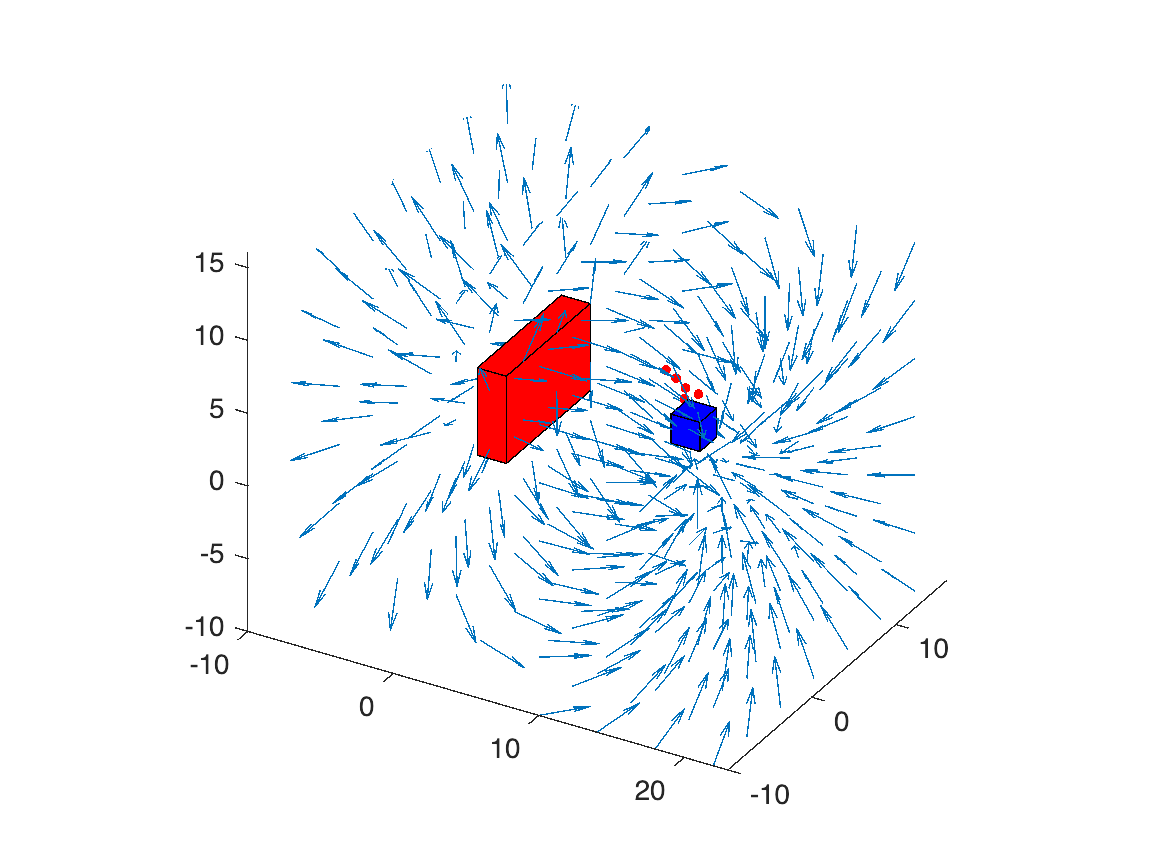

ECp = 2.9858e+11

ECn = -2.9858e+11

E = 5.9717e+11

ECp = 1.0193e+12

ECn = -1.0193e+12

E = 2.0385e+12

ECp = 4.5015e+11

ECn = -4.5015e+11

E = 9.0030e+11

ECp = 7.9355e+11

ECn = -7.9355e+11

E = 1.5871e+12

ECp = 1.2193e+12

ECn = -1.2193e+12

E = 2.4387e+12


contMal = 0;
vecID = [];

for i = 1:nG

Pcpx = posXG(i,1)-RadioGlobulo+distC(i,1);
Pcpy = posYG(i,1);
Pcpz = pmh;

Pcnx = posXG(i)+RadioGlobulo-distC(i);
Pcny = posYG(i);
Pcnz = pmh;

surf(xG+posXG(i), yG+posYG(i), zG+pmh, ...
    'FaceColor', 'r', 'EdgeColor', 'r', ...
    'FaceAlpha', '0.3');
surf(xC+Pcpx, yC+Pcpy, zC+Pcpz, ...
    'FaceColor', 'k', 'EdgeColor', 'k');
surf(xC+Pcnx, yC+Pcny, zC+Pcnz, ...
    'FaceColor', 'k', 'EdgeColor', 'k');

%---------------Carga Positiva---------------

% RxCp = Pcpx;
% RyCp = Pcpy;
% RzCp = 0;
% 
% R = sqrt(RxCp.^2 + RyCp.^2 + RzCp.^2).^3;
% 
% Ex = k2.*QCp.*RxCp./R;
% Ey = k2.*QCp.*RyCp./R;
% Ez = k2.*QCp.*RzCp./R;
% 
% ECp = sqrt(Ex.^2 + Ey.^2 + Ez.^2);

RxCp = Pcpx;
RxCn = Pcnx;

R = sqrt((RxCp-RxCn).^2);

ECp = k2.*QCp./R.^2

%---------------Carga Negativa---------------

% RxCn = Pcnx;
% RyCn = Pcny;
% RzCn = 0;
% 
% R = sqrt(RxCn.^2 + RyCn.^2 + RzCn.^2).^3;
% 
% Ex = k2.*QCn.*RxCn./R;
% Ey = k2.*QCn.*RyCn./R;
% Ez = k2.*QCn.*RzCn./R;
% 
% ECn = sqrt(Ex.^2 + Ey.^2 + Ez.^2);

ECn = k2.*QCn./R.^2

%---------------Carga Total---------------

E = ECp - ECn

if E>UE

    contMal = contMal + 1;
    vecID(contMal) = i;

end

end

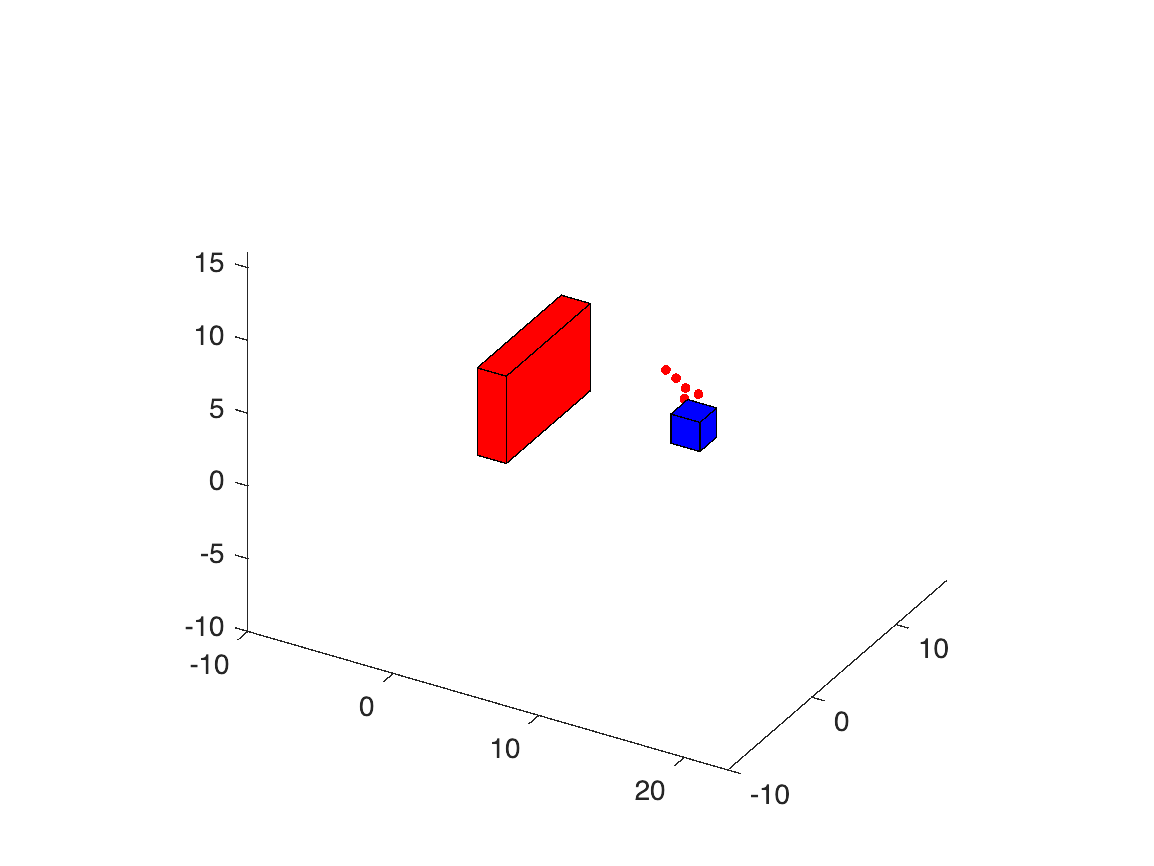


sep = l2/(contMal+1);
for i = 1:contMal

    id = vecID(i);
    %disp(id);

    posXG(id,1) = dx2-RadioGlobulo;
    posYG(id,1) = dy2 + i*sep;
end

figure;
hold on;
axis equal;

patch('Faces', carasR, 'Vertices', verticesR1, 'Facecolor', 'r');
patch('Faces', carasR, 'Vertices', verticesR2, 'Facecolor', 'b');
view(30,30);
axis([xmin, xmax, ymin, ymax, zmin, zmax]);

for i = 1:nG

Pcpx = posXG(i,1)-RadioGlobulo+distC(i,1);
Pcpy = posYG(i,1);
Pcpz = pmh;

Pcnx = posXG(i)+RadioGlobulo-distC(i);
Pcny = posYG(i);
Pcnz = pmh;

surf(xG+posXG(i), yG+posYG(i), zG+pmh, ...
    'FaceColor', 'r', 'EdgeColor', 'r', ...
    'FaceAlpha', '0.3');
surf(xC+Pcpx, yC+Pcpy, zC+Pcpz, ...
    'FaceColor', 'k', 'EdgeColor', 'k');
surf(xC+Pcnx, yC+Pcny, zC+Pcnz, ...
    'FaceColor', 'k', 'EdgeColor', 'k');
end